clc;
clear ;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s)+gensig('sine' , tfinal/50 , tfinal ,T_s)+gensig('square' , tfinal/10 , tfinal ,T_s);
Noise2=-0.2+(0.2+0.2)*rand(numel(t),1);
u=u+Noise2;
y = lsim(sysd  ,u ,t);
for i=1:numel(t)
    paras(:,i)=[d(2:end),c]';
end
uu=300;


### sudden parameter resetting

for temp=uu:numel(y)
    if floor(temp/100)==temp/100
        cc= c(2:end)+c(2:end)*(rand);
        dd=d(2:end)+d(2:end)*(rand)/2;
        paras(:,temp)=[dd,0,cc]';
    end
    
    y(temp)=[-(y(temp-1:-1:temp-4))',(u(temp-1:-1:temp-4))']*[dd,cc]';
end
    sys_dis = tf(dd ,[1 -cc], T_s)

sys_dis =
 
           -4.38 z^3 + 5.764 z^2 - 3.394 z + 0.7539
  -----------------------------------------------------------
  z^4 - 0.0005655 z^3 - 0.001558 z^2 + 0.001331 z + 0.0004097
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



    ident_change = d2c(sys_dis)

ident_change =
 
   -4015 s^3 - 9.235e04 s^2 - 7.163e05 s - 1.94e05
  -------------------------------------------------
  s^4 + 60.4 s^3 + 1776 s^2 + 2.569e04 s + 1.544e05
 
Continuous-time transfer function.



### smooth parameter variation 

% for temp=uu:numel(y)
%     paras(:,temp)=[d(2:end)+d(2:end)*.005*(sin((temp-uu)/2)),(c+c*.5*(sin((temp-uu)/2)-1))]';
%     y(temp)=[-(y(temp-1:-1:temp-4))',(u(temp:-1:temp-4))']*paras(:,temp);
% end
%     sys_dis = tf(c+c*.01*(sin(.01*(temp-uu))-1)' ,[1 -d(2:end)+d(2:end)*.001*(sin(.01*(temp-uu)))'], T_s)
%     ident_change = d2c(sys_dis)

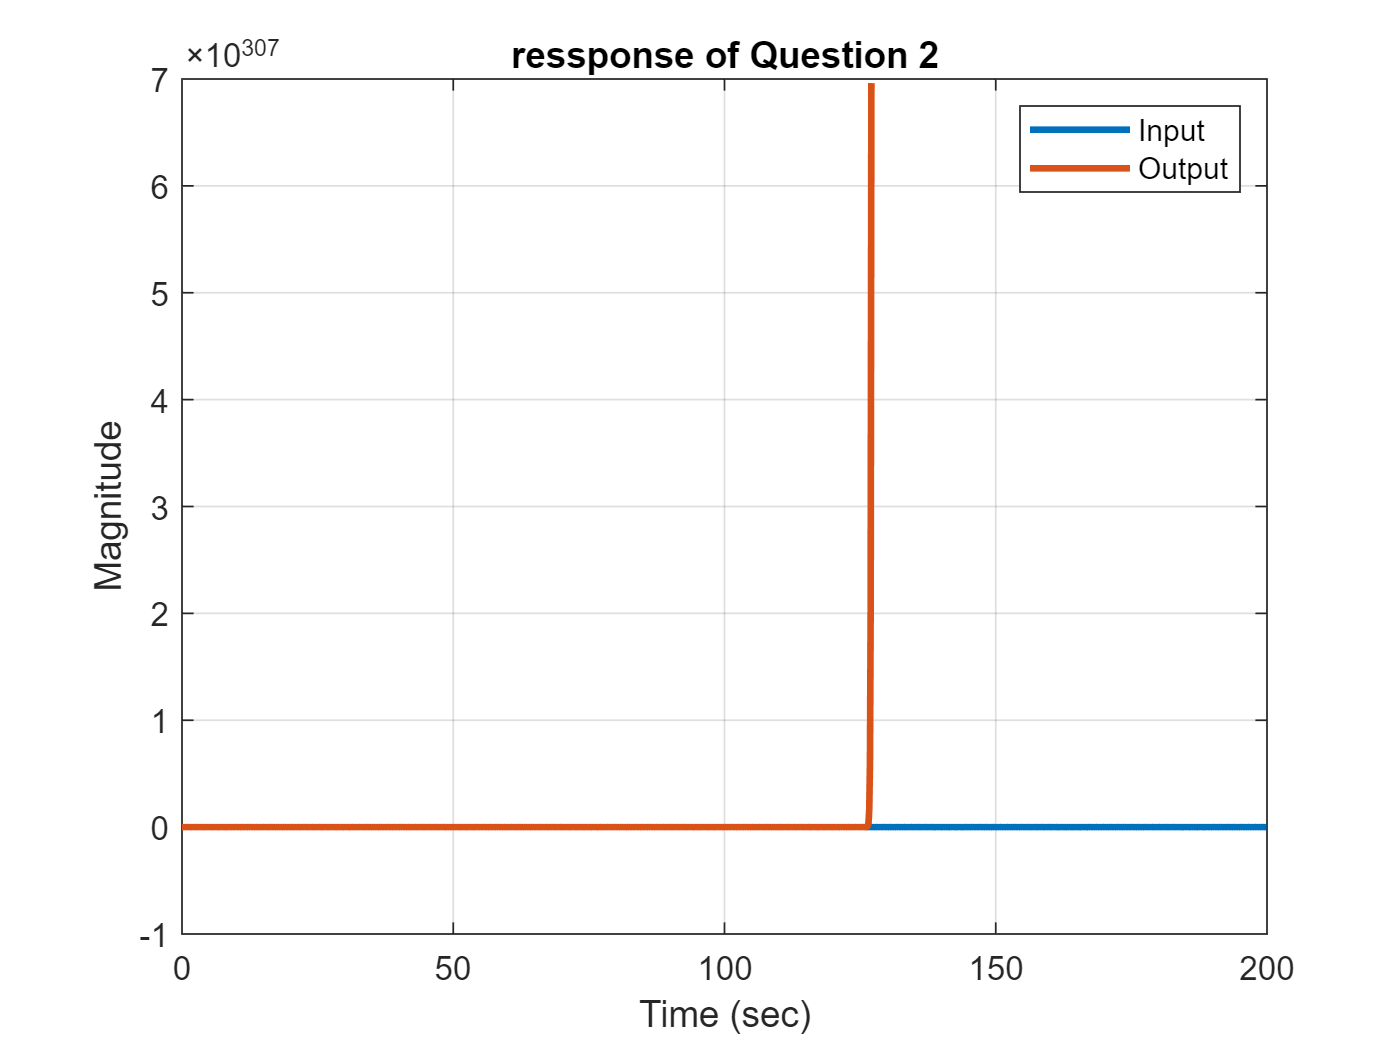

plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitude') ;
title('ressponse of Question 2') ;
grid on
legend('Input','Output') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den;
P = 1e12*eye(Nv) ;
theta=[Nv,N];
theta(1:Nv,1:30) = 5*ones(Nv,30) ;
e=[numel(y),1];
e=zeros(numel(y),1);
phi=[];
Eror=zeros(1,N);
norm=zeros(N,1);
y_hat(1:N,1)=zeros(N,1);


seed=10

seed = 10

GG=max(Parameters_in_num,Parameters_in_den)

GG = 4

for i = GG+1:N
    phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;

    if mod(i,seed)==0
        P = 1e12*eye(Nv);
    else
        P = (eye(Nv) - K*phi(:,i)')*P;
    end
    y_hat(i)=phi(:,i)'*theta(:,i-1);
    theta(:,i) = theta(:,i-1) + K*(y(i)-y_hat(i)); 

    norm(i)=(norm(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2)/2;
    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end

Bode

% ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)
% ident_analog = d2c(ident_dis)
% bode(ident_analog ,'g*',ident_change )
% legend('model ','system')

RLS Convergence

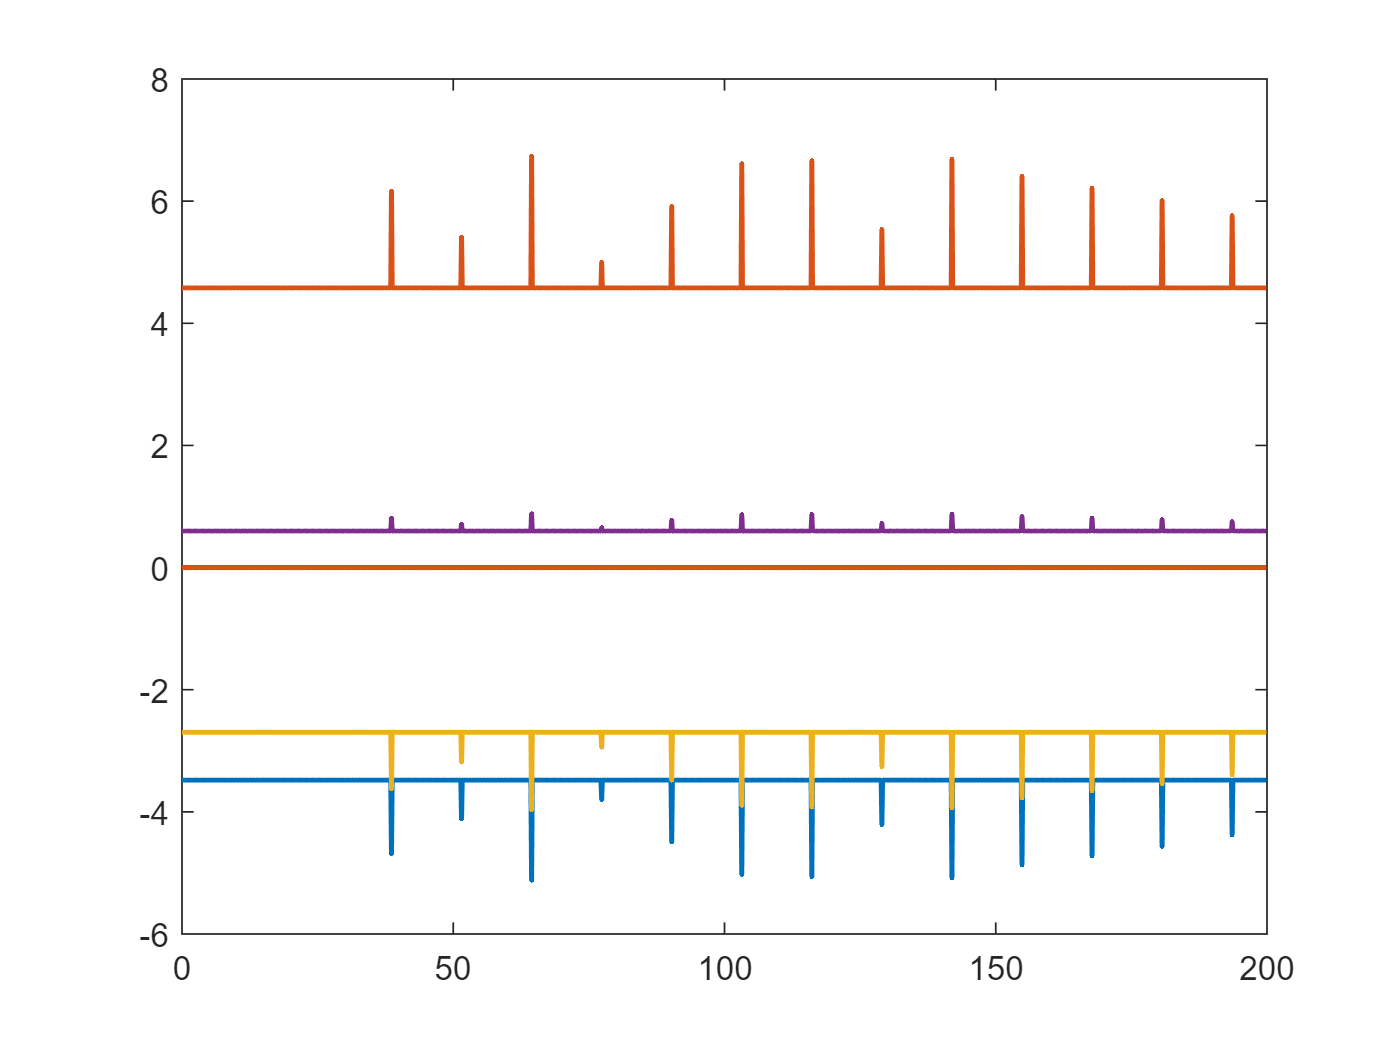

plot(t ,paras(:,:) , 'LineWidth' , 1.5)

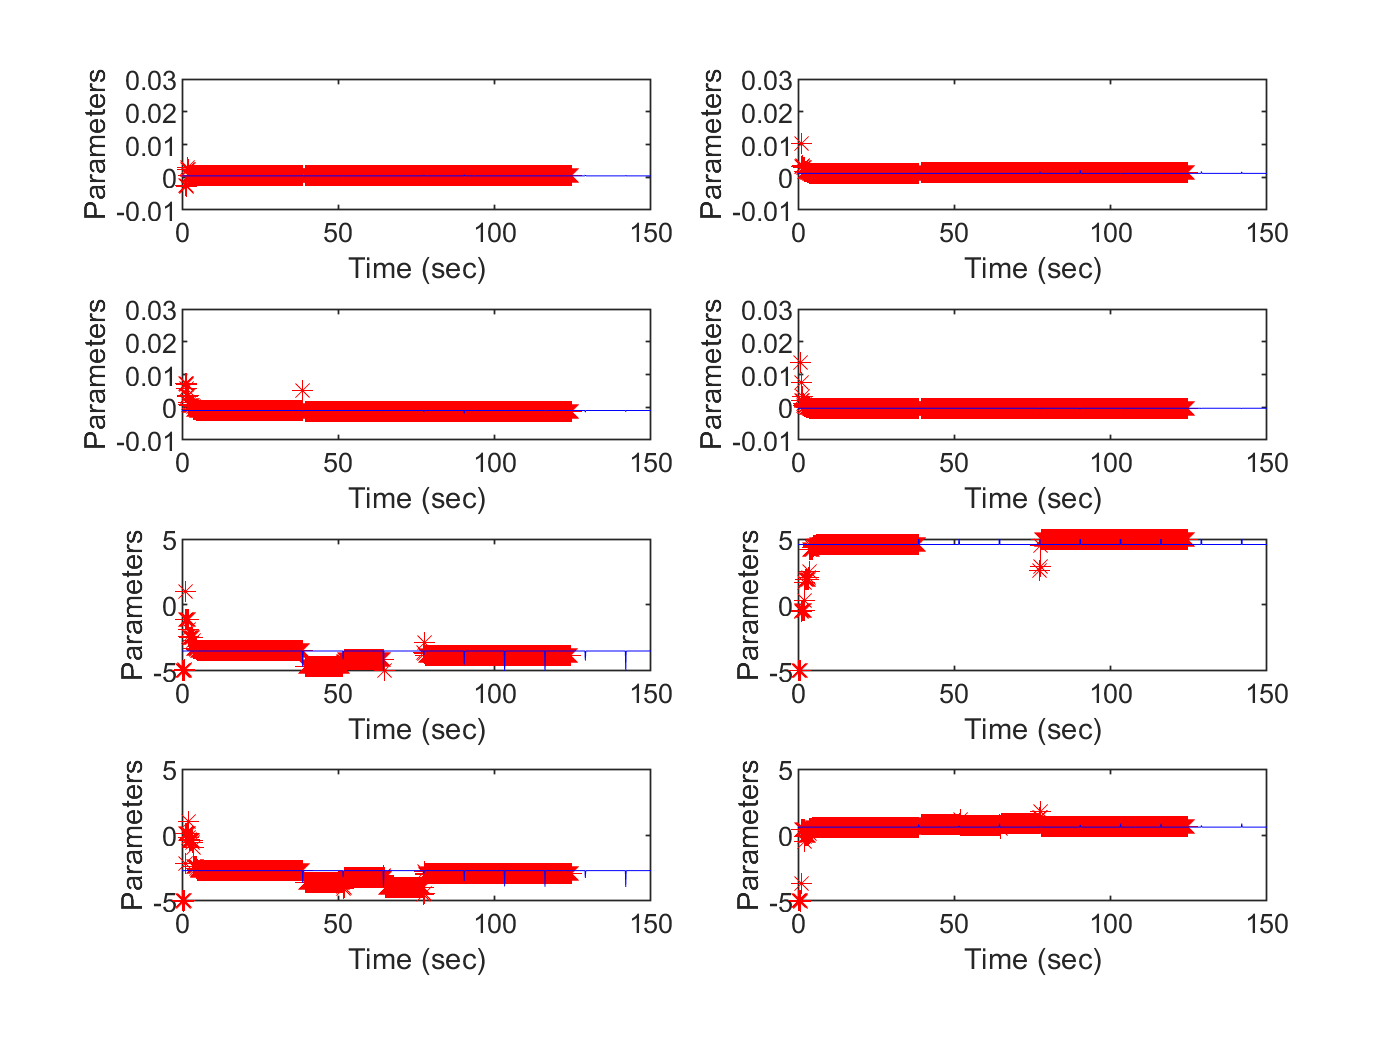

figure
grid on
for i=1:4
    subplot(4,2,i)
    plot(t , theta(4+i,:),'r*' ,t , paras(5+i,:) ,'b','LineWidth' , 0.25) ;
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
    xlim([0 150])
    ylim([-0.01  0.03])
end
for i=1:4
    subplot(4,2,4+i)
    plot(t , -theta(i,:) ,'r*',t , paras(i,:) ,'b', 'LineWidth' , 0.25) ;
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
     xlim([0 150])
     ylim([-5  5])
end

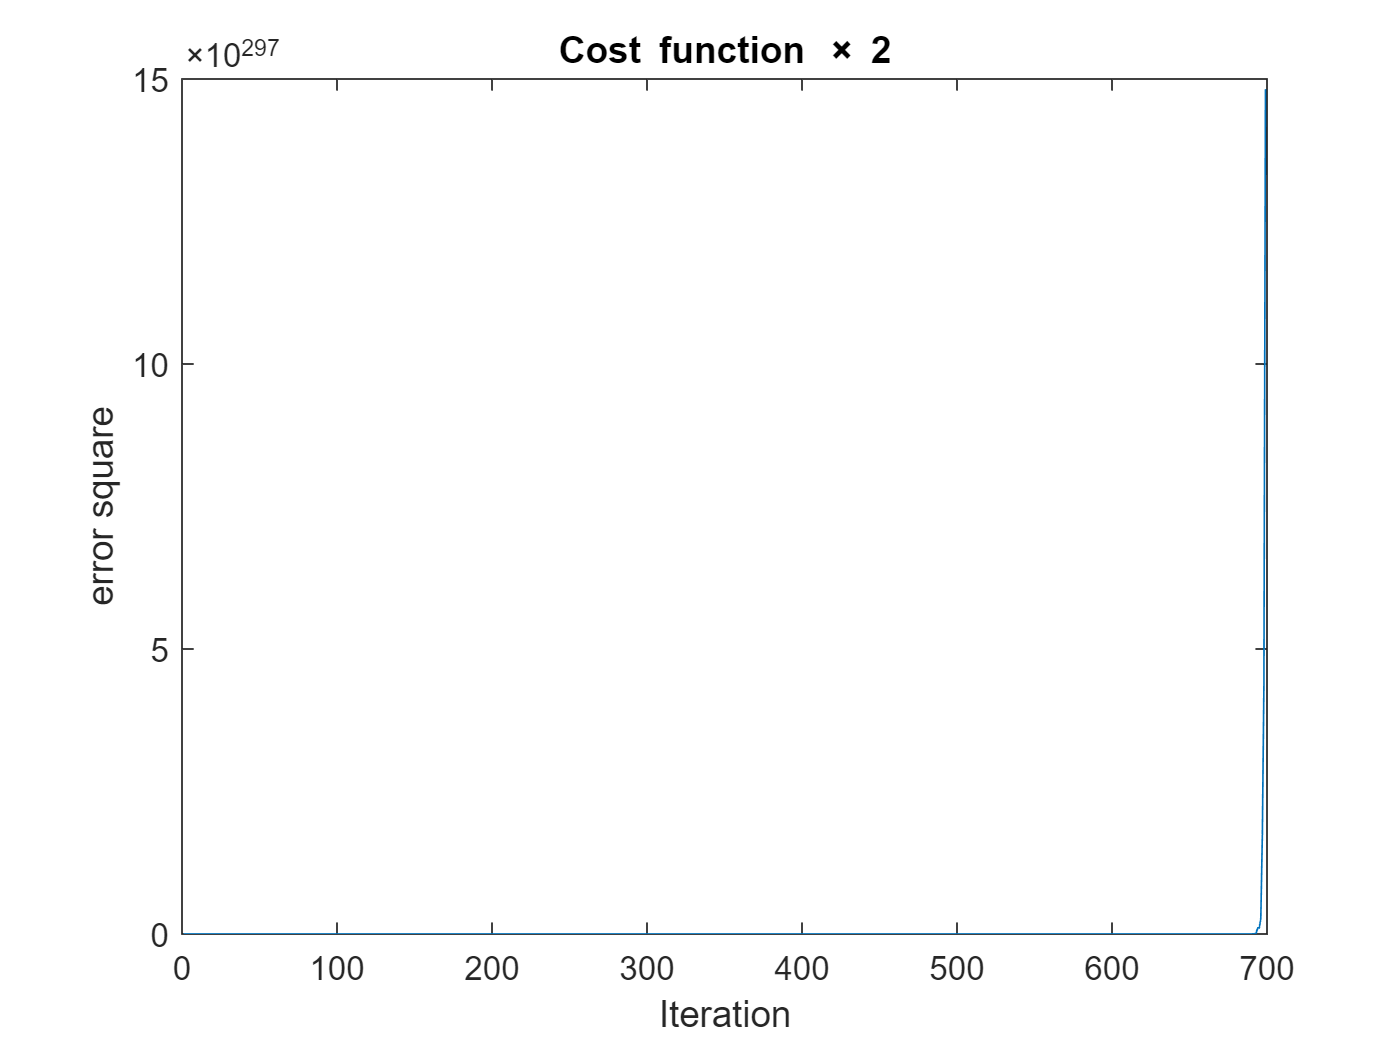

figure
plot(1:1:N,Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;

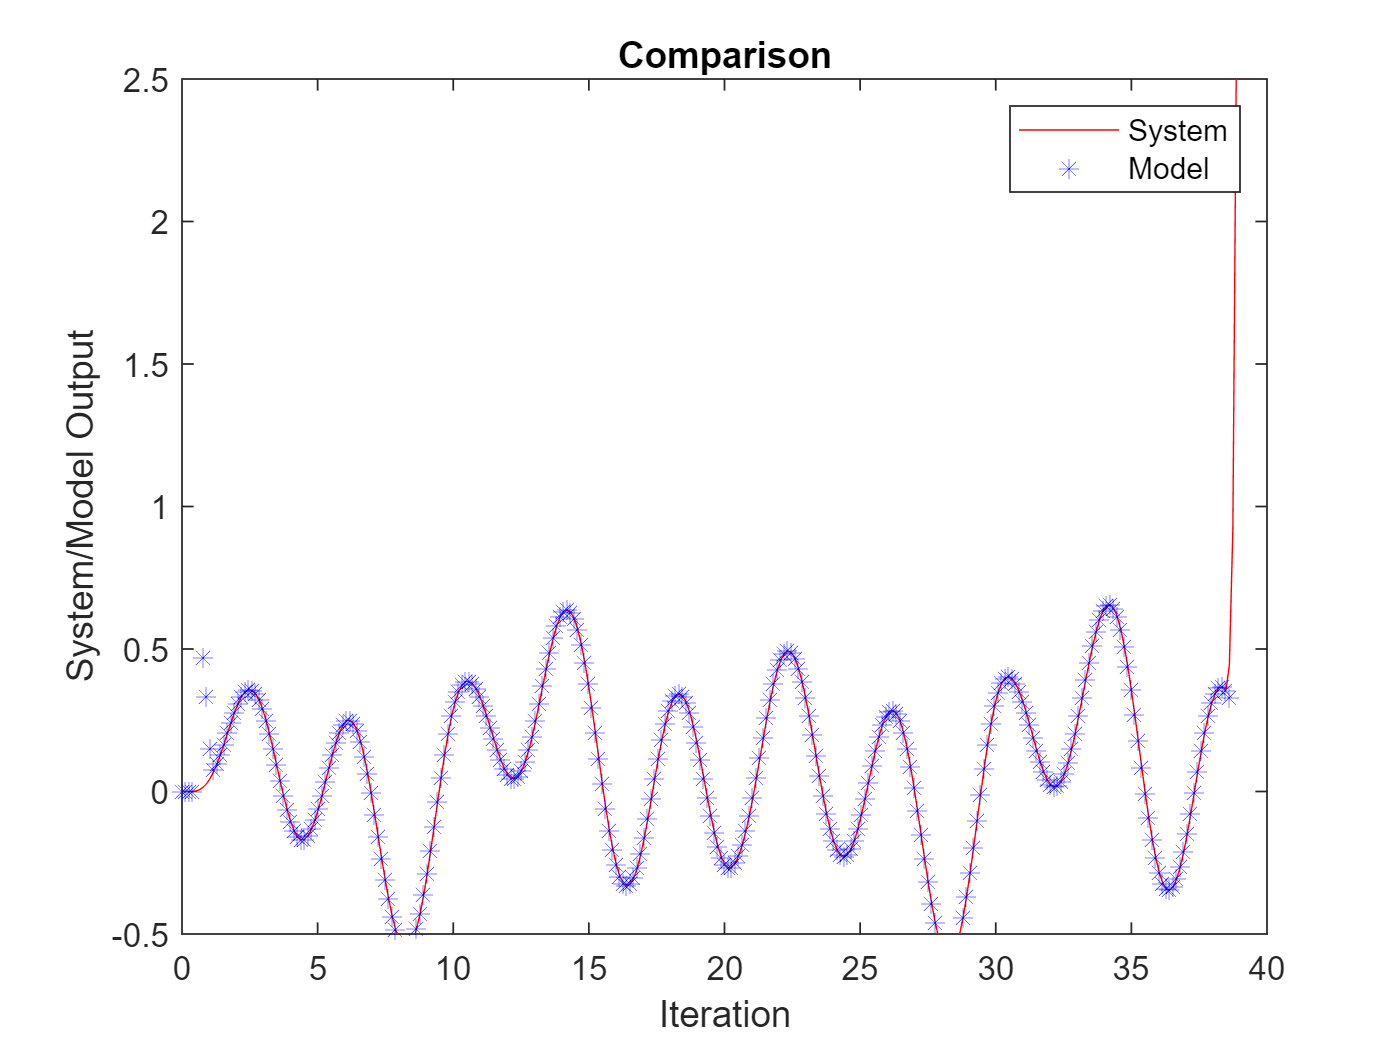

plot(t,y,'r',t,y_hat,'b*','LineWidth',0.15)
xlabel('Iteration') ;
ylabel('System/Model Output') ;
title('Comparison') ;
xlim([0 40])
ylim([-0.5 2.5])
legend('System','Model')